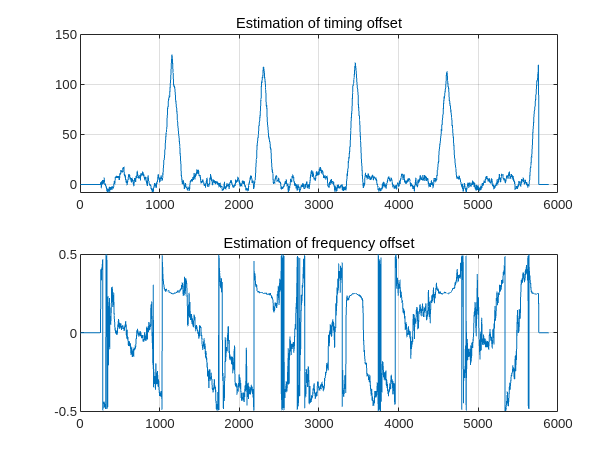

%% ML estimation of time and frequency offset in OFDM systems
% Algorithm authors : J.J. van de Beek, M. Sandell, and P.O. B膐rjesson
% Prepared by Hiren Gami

clc
clear all;
%% Parameter declaration according to paper
Nfft = 1024;
Ncp = 128;
Nsym = 6;
FreqOffset = 0.25;
SNRdb = 15;
theta = 256;
%% OFDM symbol generation
data = 2*randi([0 1],1, Nsym*Nfft)-1; % BPSK data

Tx = zeros(1,Nsym*(Nfft+Ncp));
OFDMsym = zeros(1,Nfft);  
for sym = 1:Nsym
    OFDMsym = ifft(data(Nfft*(sym-1)+1:(Nfft*sym)),Nfft)*sqrt(Nfft);
    Tx((Nfft+Ncp)*(sym-1)+1:(Nfft+Ncp)*sym) = [OFDMsym(Nfft-Ncp+1:Nfft) OFDMsym];
end

%% AWGN channel
snr = 10^(-SNRdb/10);
noise = sqrt(snr/2)*(randn(1,Nsym*(Nfft+Ncp))+1i*randn(1,Nsym*(Nfft+Ncp)));
Rx = exp(1i*2*pi*FreqOffset*(0:length(Tx)-1)./Nfft).*Tx + noise; 

%% ML estimation of timing and frequency offset
PHI_sum = zeros(1,Nsym*(Nfft+Ncp)-Nfft);
GM_sum = zeros(1,Nsym*(Nfft+Ncp)-Nfft);

for n = theta:Nsym*(Nfft+Ncp)-(Nfft+Ncp)
    PHI=0;GM=0;
    for m = n:n+Ncp-1    
        PHI = PHI+ (Rx(m)*conj(Rx(m)) + Rx(m+Nfft)*conj(Rx(m+Nfft)));
        GM = GM+ Rx(m)*conj(Rx(m+Nfft));    
    end
    PHI_sum(n) = abs(GM)- (snr/(snr+1))*PHI;
    GM_sum(n) = -angle(GM)/(2*pi);
end

%% Estimation results display

subplot(2,1,1);plot(PHI_sum);title('Estimation of timing offset');grid on;
subplot(2,1,2);plot(GM_sum);title('Estimation of frequency offset');grid on;


[value,thetaEst]=findpeaks(PHI_sum,'minpeakdistance',Nfft);
disp(thetaEst);

        1153        2300        3457        4609        5760



disp(GM_sum(thetaEst));

    0.2467    0.2493    0.2495    0.2504    0.2500

